# Task 1

## Import and plotting

clear all
S1 = load('large_data.mat');
fieldnames(S1);
large_data = S1.large_data

large_data =     9.5122
    9.4145
    9.2901
    9.3347
    9.3087
    9.4460
    9.2249
    9.4079
    9.2437
    9.3643


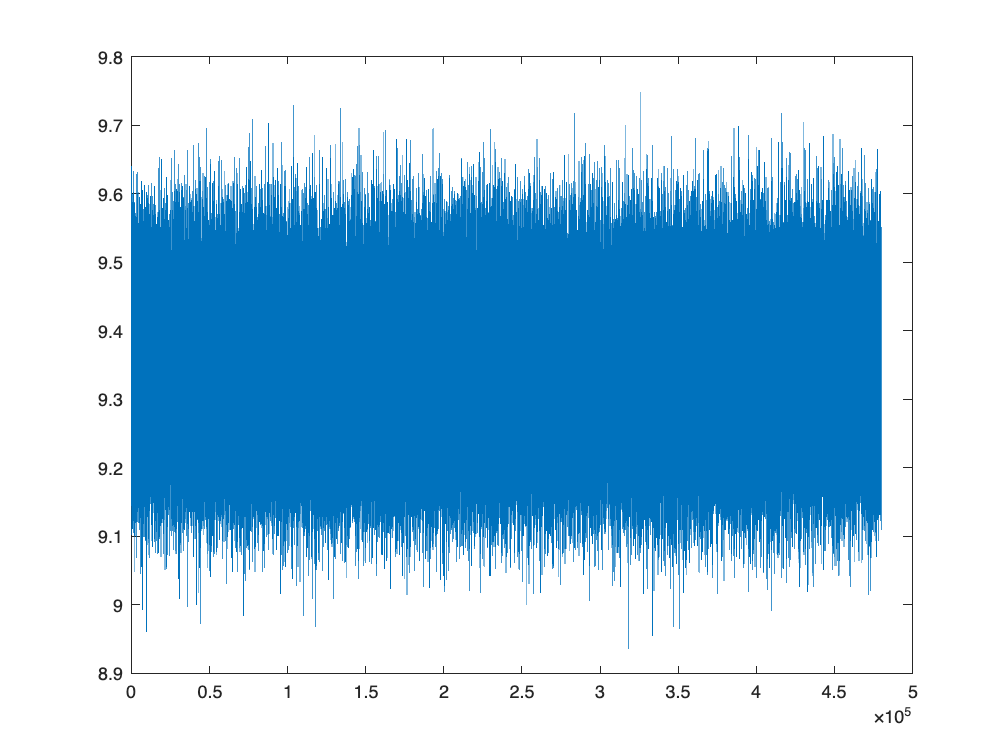

plot(large_data);

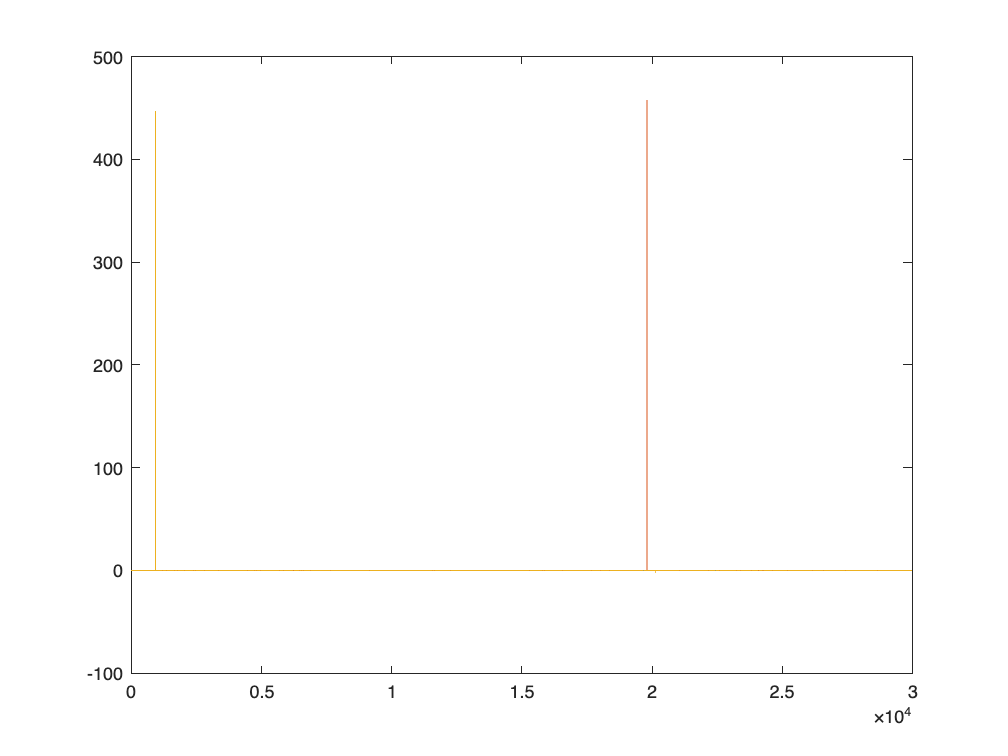

S2 = load("imu_data_stationary.mat");
fieldnames(S2);
imu_data123 = S2.imu_data(:,1:3); % select one channel
imu_data1 = S2.imu_data(:,1); %select one col
plot(imu_data123);

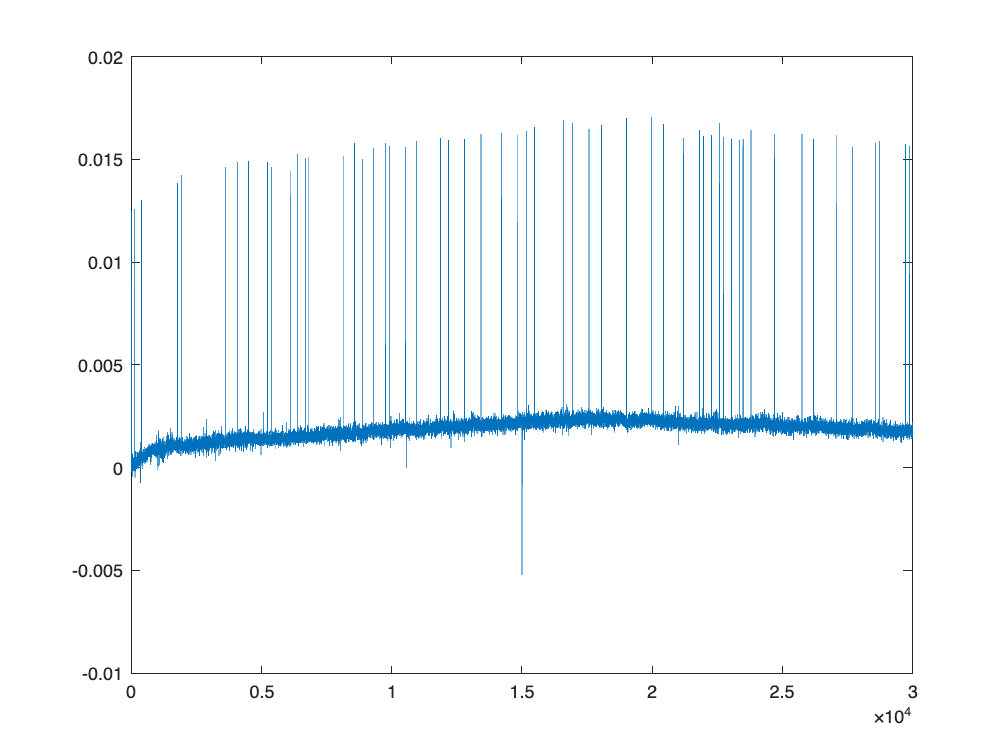

plot(imu_data1)

### The imu data is not very plot friendly as a channel before scaling i suppose.

## Histogram plot

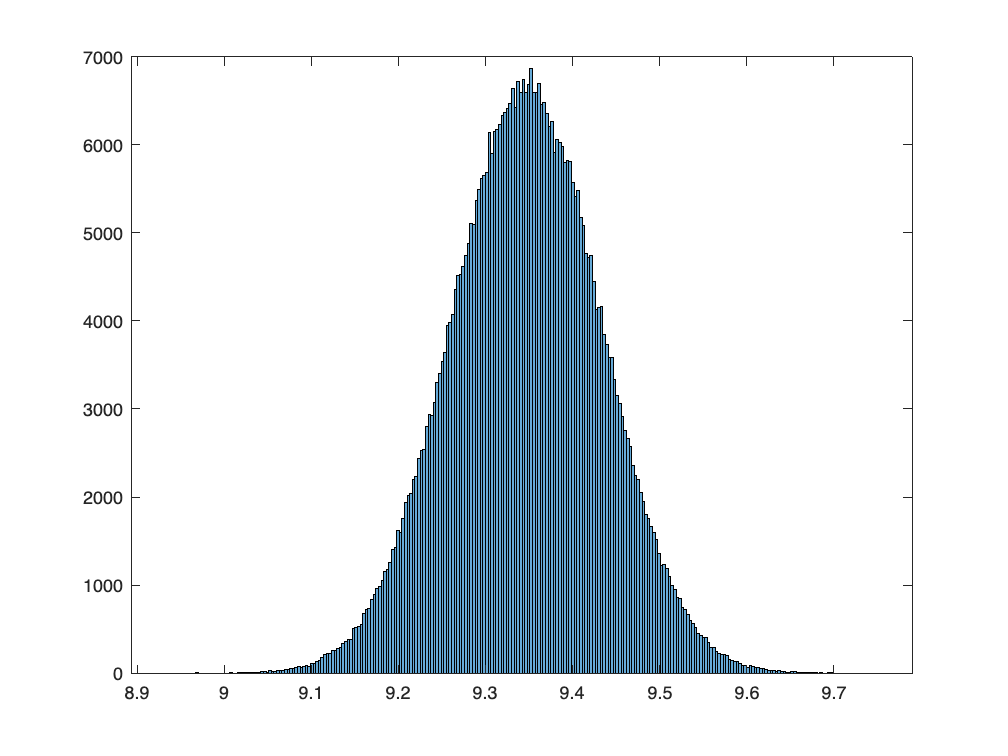

histogram(large_data)

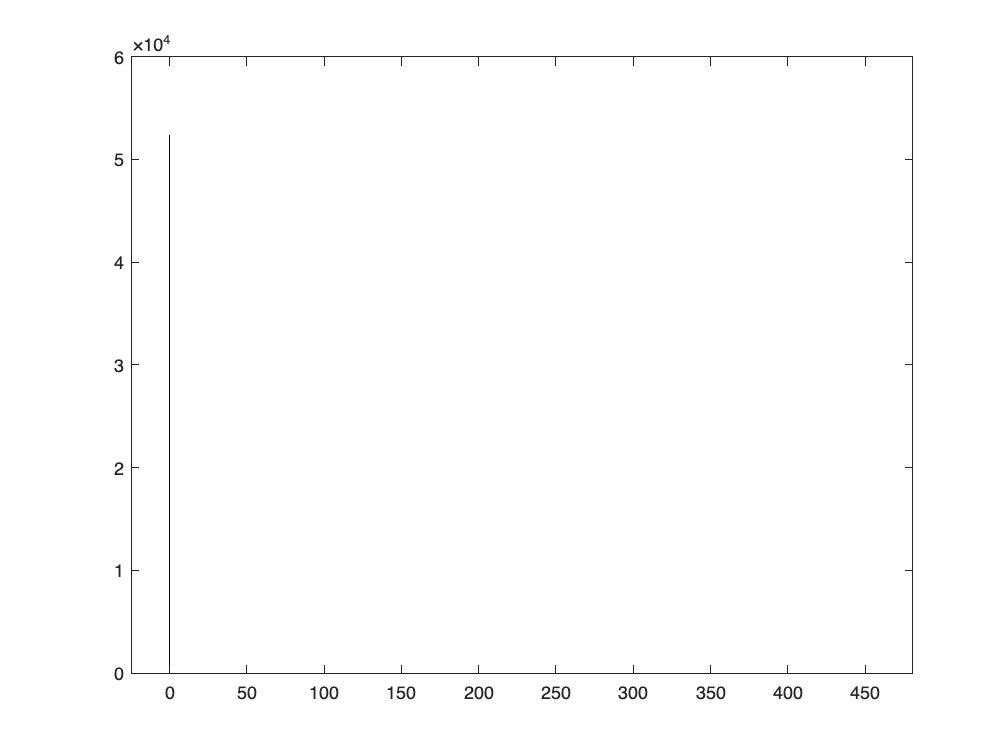

histogram(imu_data123)

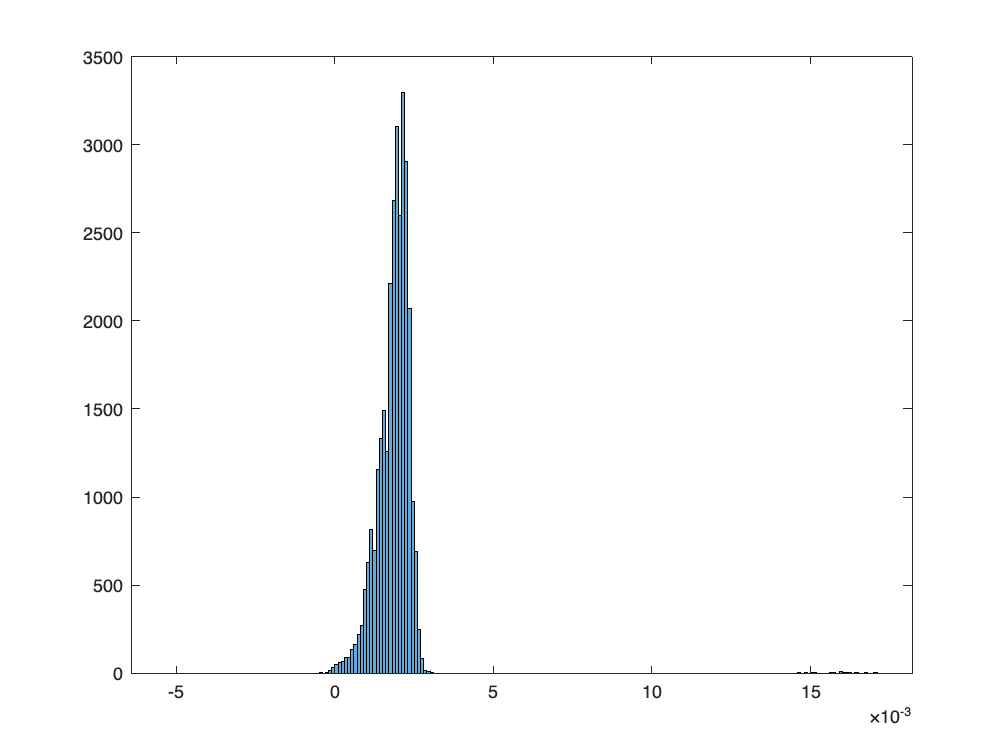

histogram(imu_data1)

## Mean and std of the datasets before undersampling

std_large = std(large_data)

std_large = 0.0861

mean_large = mean(large_data)

mean_large = 9.3469

std_imu123 = std(imu_data123)

std_imu123 =     0.0008    2.6430    2.5771


mean_imu123 = mean(imu_data123)

mean_imu123 =     0.0019    0.0126    0.0163


## Undersampling

k = 480000/64400;
large_data_u = large_data(1:k:length(large_data));

## Standardization

large_data_u_std = std(large_data_u);
large_data_u_mean = mean(large_data_u);
large_data_u_standardized = (large_data_u - large_data_u_mean)./large_data_u_std;

## Mean and standard deviation of the standardized dataset (large_data):

large_data_u_standardized_mean = mean(large_data_u_standardized)

large_data_u_standardized_mean = 1.0836e-13

large_data_u_mean

large_data_u_mean = 9.3465

large_data_u_standardized_std = std(large_data_u_standardized)

large_data_u_standardized_std = 1.0000

large_data_u_std

large_data_u_std = 0.0859

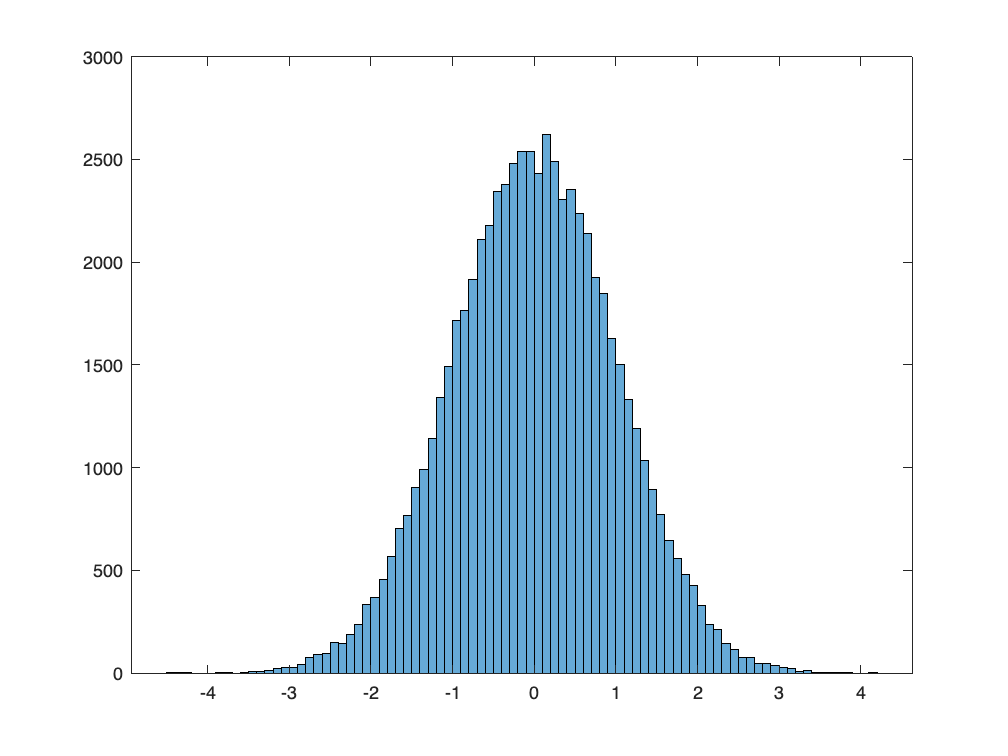

histogram(large_data_u_standardized)

### As expected, the standardized dataset mean is (exremely close to) 0, and the std is dead on 1.

## Some standardization of the imu_data

imu123_standardized = (imu_data123 - mean_imu123)./std_imu123;

imu123_standardized_mean = mean(large_data_u_standardized)

imu123_standardized_mean = 1.0836e-13

mean_imu123

mean_imu123 =     0.0019    0.0126    0.0163


imu123_standardized_std = std(imu123_standardized)

imu123_standardized_std =     1.0000    1.0000    1.0000


std_imu123

std_imu123 =     0.0008    2.6430    2.5771


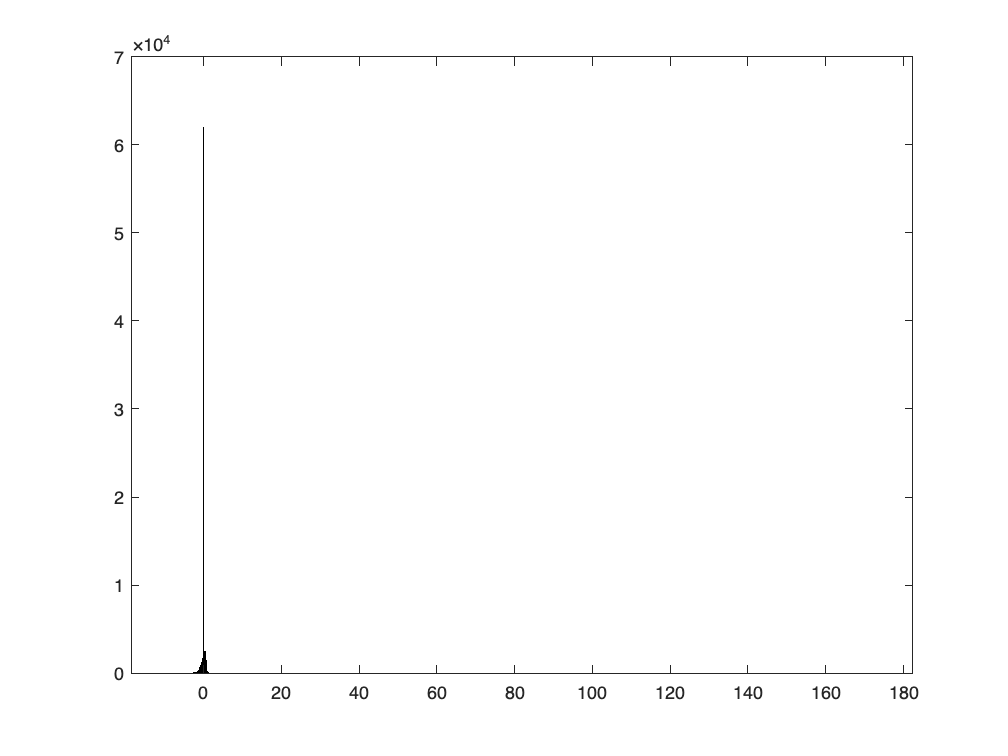

histogram(imu123_standardized)

# Task 2

S3 = load('corrupted_data.mat');
fieldnames(S3);
corr_data = S3.corrupted_data

corr_data =     9.5122
    9.4145
    9.2901
    9.3347
    9.3087
    9.4460
    9.2249
    9.4079
    9.2437
    9.3643


plot(large_data);

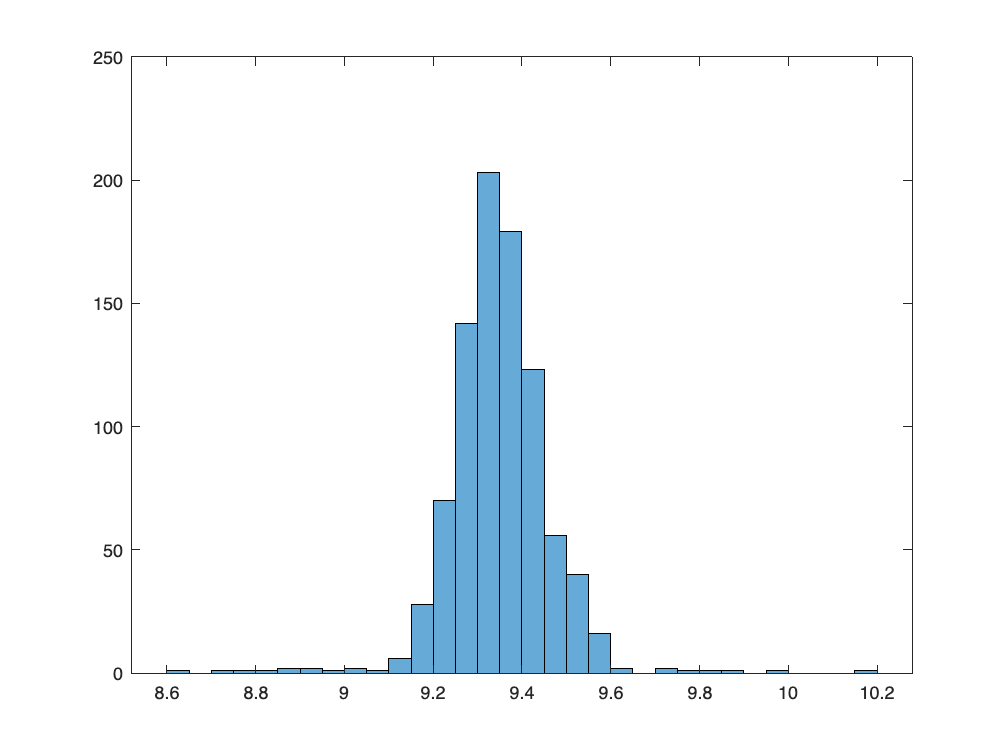

histogram(corr_data)

### What i can tell is that the data is more binned than before. We can try increasing the bins:

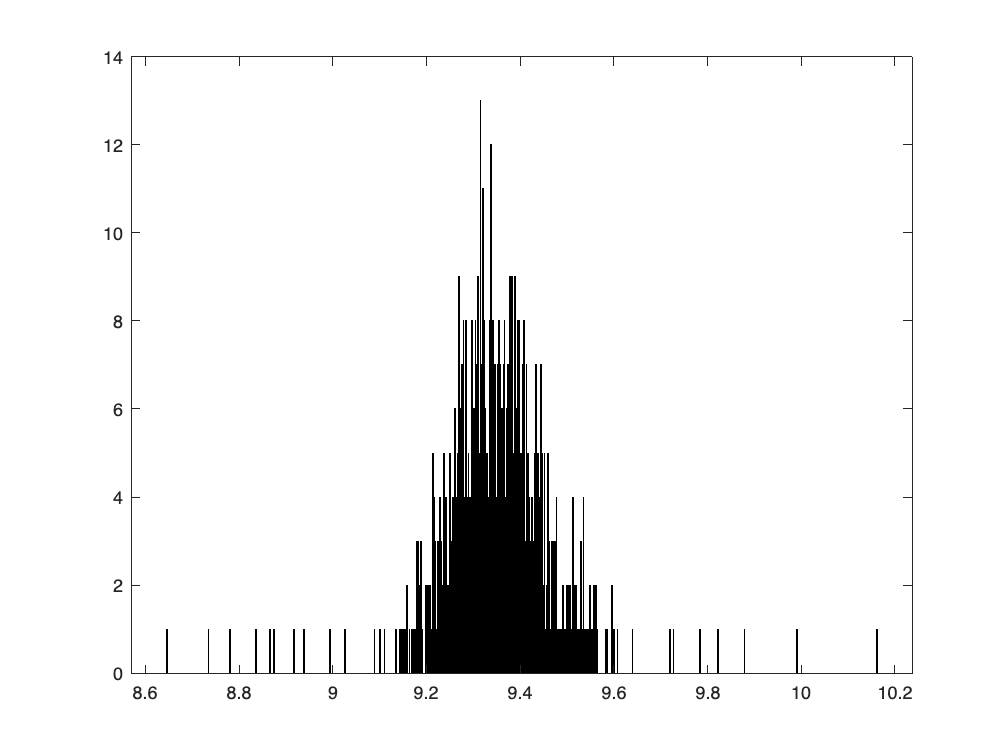

histogram(corr_data,1000)

### This might tell us that the dataset is smaller than before, or that the values are not that spread out as the last ones. (has a lower std).

corr_data_filled = fillmissing(corr_data,'pchip');

### Got this recommended by the world famous chatbot as the best quickest way of interpolating the missing values. 

## Outlier removal

mean_corr = mean(corr_data_filled);
std_corr = std(corr_data_filled);

z_score_corr = (corr_data_filled - mean_corr)./std_corr

z_score_corr =     1.3753
    0.5478
   -0.5058
   -0.1280
   -0.3483
    0.8146
   -1.0580
    0.4919
   -0.8988
    0.1226


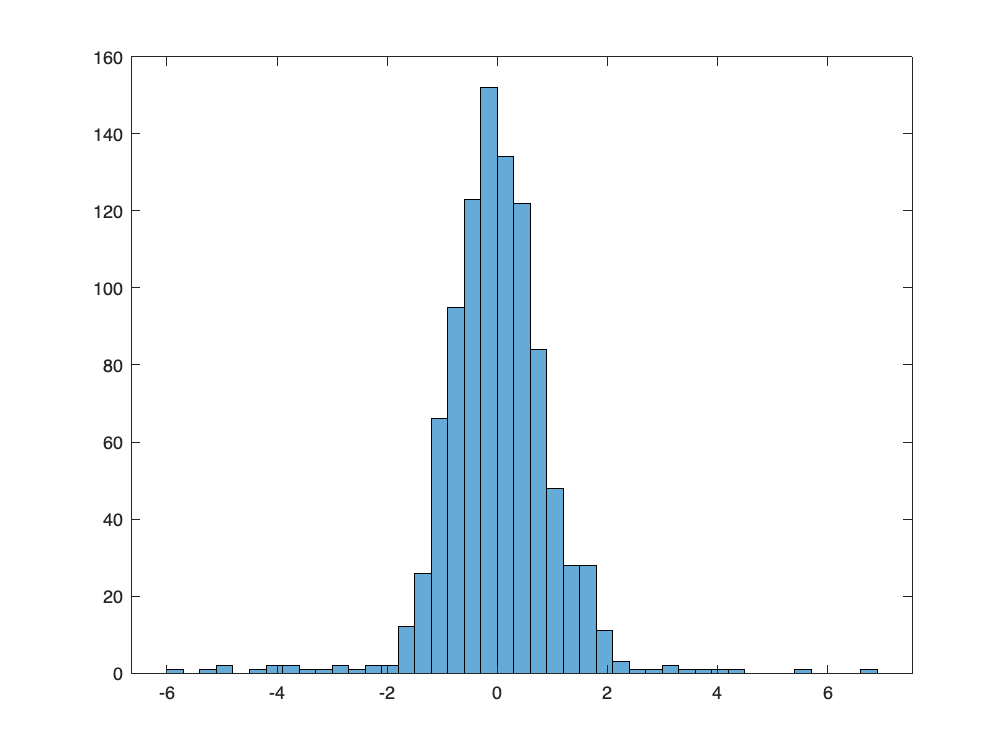

histogram(z_score_corr)

## remove outliers

z_score_corr_clean = z_score_corr(abs(z_score_corr) <= 3);
removed_outliers = z_score_corr(abs(z_score_corr) >= 3);

## replace with NaNs instead of removing

z_score_corr(abs(z_score_corr) >= 3) = NaN;
z_score_corr_filled = fillmissing(z_score_corr,"pchip")

z_score_corr_filled =     1.3753
    0.5478
   -0.5058
   -0.1280
   -0.3483
    0.8146
   -1.0580
    0.4919
   -0.8988
    0.1226


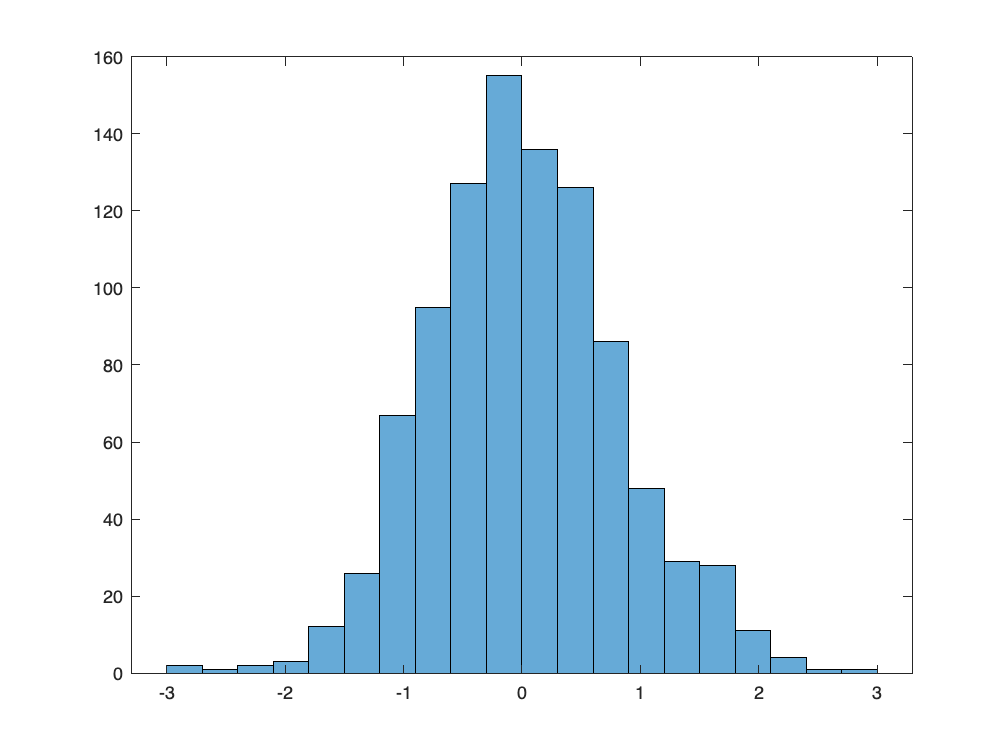

histogram(z_score_corr_filled)

### I have never seen this method before. Neither have I ever seen outlier detection using KNN. Looks promising, although we only sampled 19 rows, it might have a big impact on big noisy datasets? 

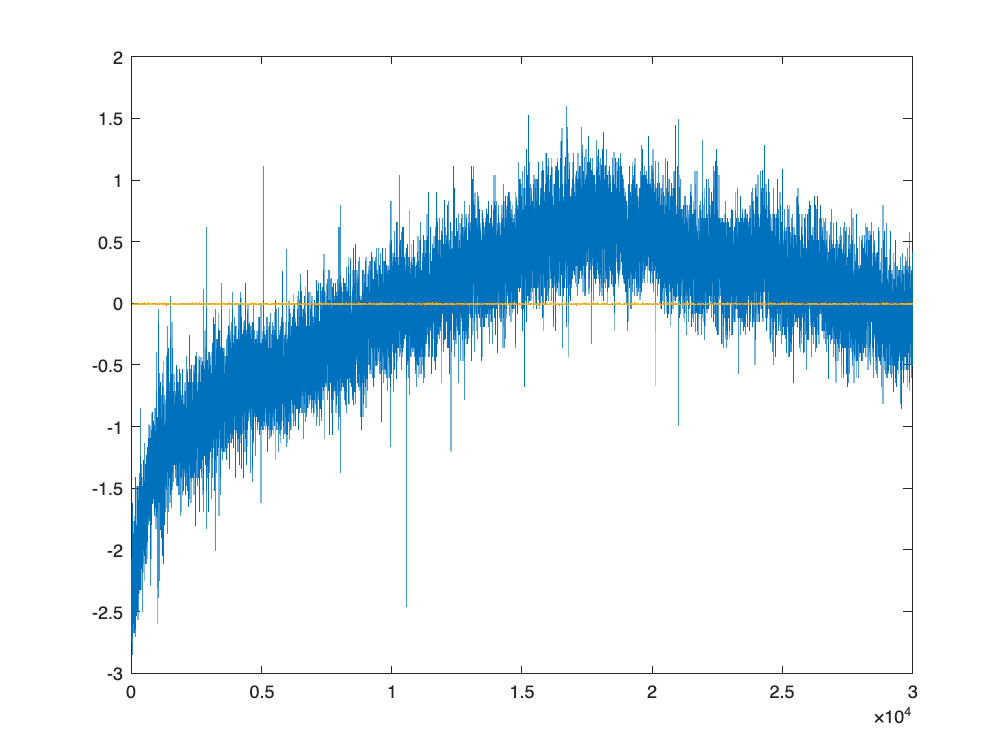


imu_data = S2.imu_data;
z_score_imu = (imu_data - mean(imu_data))./std(imu_data);
imu_outliers = z_score_imu(abs(z_score_imu) >= 3);
z_score_imu(abs(z_score_imu) >= 3.0) = NaN;
z_score_imu = fillmissing(z_score_imu,"pchip");
plot(z_score_imu(:,1:3))

## KNN method (please read below section)


X = imu_data;                    
k = 9;
cont = 196 / 30000; % contamination fraction

% kNN distances (euclidean)
Mdl = createns(X,'NSMethod','kdtree');
[idx, dist] = knnsearch(Mdl, X, 'K', k+1);   % includes self in first col
avgDist = mean(dist(:,2:end), 2);            % exclude self

% Threshold at (1 - contamination) quantile
cutoff = quantile(avgDist, 1 - cont);
outliers = avgDist >= cutoff;                % logical (n_samples x 1)

% Replace entire outlier rows, then interpolate over time per column
X_clean = X;
X_clean(outliers, :) = NaN;
X_clean = fillmissing(X_clean, 'linear', 1); % interpolate down rows (time)
X_clean = fillmissing(X_clean, 'nearest', 1);% edge fill as fallback

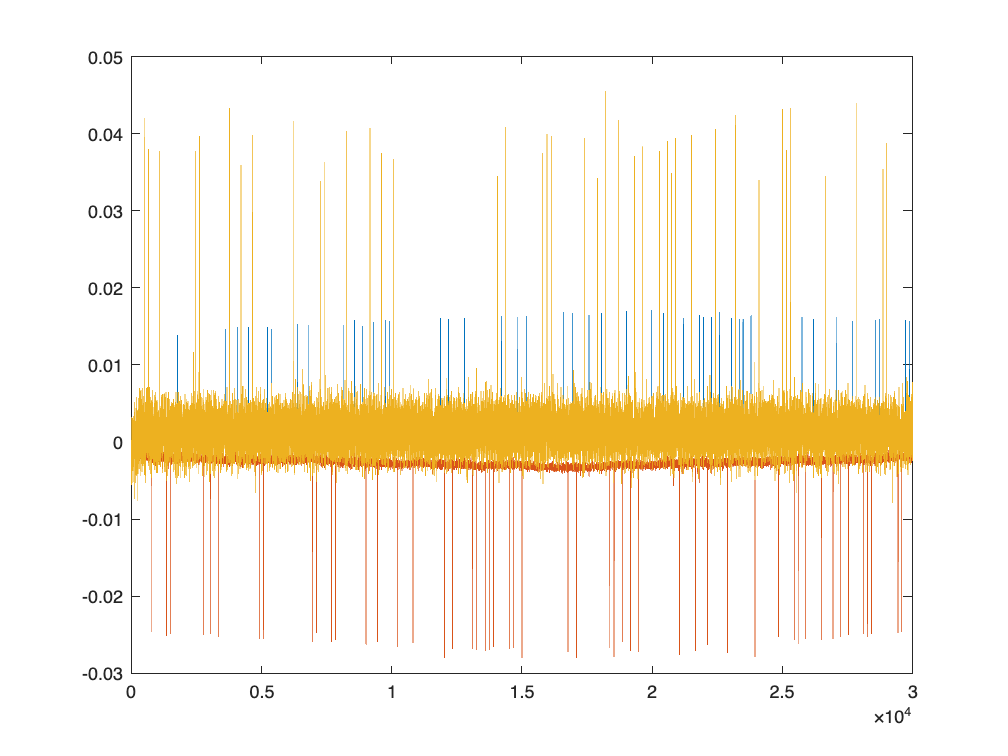

plot(X_clean(:,1:3))

### This code is generated by chatGPT, based on the article (https://kunalbharadkar.medium.com/outlier-anomalies-detection-using-unsupervised-machine-learning-8a25e66de85c). Seemed pretty advanced, asked my friend about it and he said that the KNN part was scrapped from the lab, because lack of labels(?). It seems to have done something by removing most of the values above 0.1, which broke the dataset. I still think i understand the concept of outlier detection using KNN, as the KNN works on distances (clusters), together with the contamination rate that should be set to around the predicted share of outliers. Hence we should be able to detect outliers based on points not being contaminated by a cluster.